# HW 7 - Optimization

## Problem 1- Golden-section search method

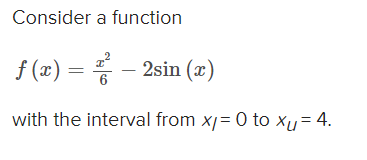

Find the minimum of the given function using the M-file. (Round the final answers to four decimal places. Include a minus sign if necessary.)

xl = 0; xu = 4;
f = @(x) x.^2/6-2*sin(x);
%help goldmin
[x,fx,ea,iter]=goldmin(f,xl,xu)

x = 1.3448

fx = -1.6477

ea = 9.8810e-05

iter = 30

## Problem 2 - fminsearch

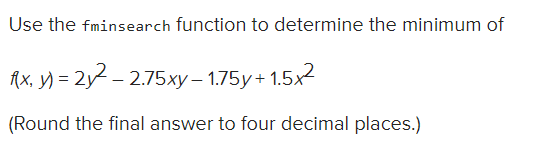

f = @(x) 2*x(2)^2-2.75*x(1)*x(2)-1.75*x(2)+1.5*(x(1))^2;

[x1, x2] = meshgrid(-500:10:500, -500:10:500);

% Evaluate g(x1, x2) over the grid
G = 2*x2.^2-2.75*x1.*x2-1.75*x2+1.5.*x1.^2;

% Plot 3D surface
figure;
surf(x1, x2, G);
hold on;

help fminsearch

 fminsearch Multidimensional unconstrained nonlinear minimization (Nelder-Mead).
    X = fminsearch(FUN,X0) starts at X0 and attempts to find a local minimizer 
    X of the function FUN.  FUN is a function handle.  FUN accepts input X and 
    returns a scalar function value F evaluated at X. X0 can be a scalar, vector 
    or matrix.
 
    X = fminsearch(FUN,X0,OPTIONS)  minimizes with the default optimization
    parameters replaced by values in the structure OPTIONS, created
    with the OPTIMSET function.  See OPTIMSET for details.  fminsearch uses
    these options: Display, TolX, TolFun, MaxFunEvals, MaxIter, FunValCheck,
    PlotFcns, and OutputFcn.
 
    X = fminsearch(PROBLEM) finds the minimum for PROBLEM. PROBLEM is a
    structure with the function FUN in PROBLEM.objective, the start point
    in PROBLEM.x0, the options structure in PROBLEM.options, and solver
    name 'fminsearch' in PROB

[xmin, fval] = fminsearch(f,[400 -300])

xmin =     1.0845    1.1831


fval = -1.0352

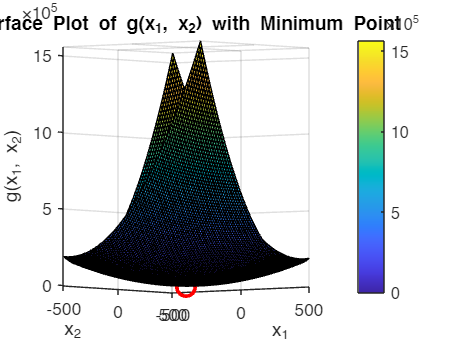


plot3(min(1), min(2), fval, 'ro', 'MarkerSize', 10, 'LineWidth', 2);
xlabel('x_1');
ylabel('x_2');
zlabel('g(x_1, x_2)');
title('Surface Plot of g(x_1, x_2) with Minimum Point');
colorbar;
grid on;
view(45, 30);

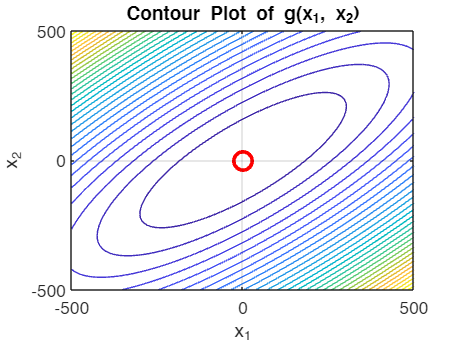


% Optional: Add a contour plot for clarity
figure;
contour(x1, x2, G, 30);
hold on;
plot(xmin(1), xmin(2), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
xlabel('x_1');
ylabel('x_2');
title('Contour Plot of g(x_1, x_2)');
grid on;
hold off;